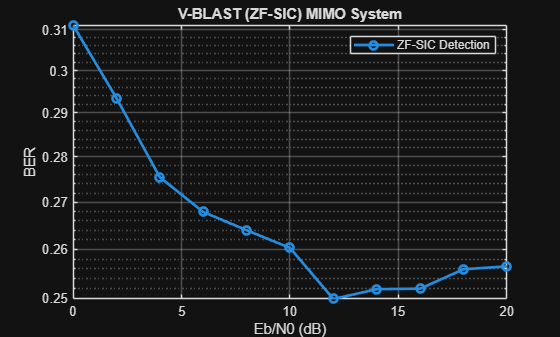

clc; clear; close all;

%% Parameters
Nt = 2;                 % Transmit antennas
Nr = 2;                 % Receive antennas
N = 1e4;                % Symbols per stream
EbN0_dB = 0:2:20;

M = 4;                  % QPSK
k = log2(M);

ber = zeros(size(EbN0_dB));

%% Generate Data
bits = randi([0 1], Nt*N*k, 1);
symbols = qammod(bits, M, 'InputType', 'bit', 'UnitAveragePower', true);
symbols = reshape(symbols, Nt, []);

%% ================= Simulation =================
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(k*EbN0);
    
    err = 0;
    total = 0;
    
    for n = 1:N
        
        % Channel
        H = (randn(Nr,Nt) + 1j*randn(Nr,Nt))/sqrt(2);
        
        % Transmit
        x = symbols(:,n);
        noise = sqrt(noise_var/2)*(randn(Nr,1) + 1j*randn(Nr,1));
        y = H*x + noise;
        
        % V-BLAST Detection
        H_rem = H;
        y_rem = y;
        detected = zeros(Nt,1);
        order = zeros(Nt,1);
        
        for stage = 1:Nt
            
            % ZF filter
            W = pinv(H_rem);
            
            % Compute post-detection SNR (norm-based)
            snr_stream = 1 ./ sum(abs(W).^2,2);
            
            % Select best stream
            [~, idx] = max(snr_stream);
            
            % Detect symbol
            w = W(idx,:);
            x_hat = w * y_rem;
            
            % Hard decision
            sym_detect = qamdemod(x_hat, M, 'UnitAveragePower', true);
            sym_detect = qammod(sym_detect, M, 'UnitAveragePower', true);
            
            % Save result
            detected(order==0);
            order(stage) = idx;
            
            % Cancel interference
            h_col = H_rem(:,idx);
            y_rem = y_rem - h_col * sym_detect;
            
            % Remove detected column
            H_rem(:,idx) = [];
            
            % Store detected symbol
            detected(stage) = sym_detect;
        end
        
        % Reorder detected symbols (approximate)
        x_hat_final = detected;
        
        % Convert to bits
        bits_hat = qamdemod(x_hat_final, M, 'OutputType', 'bit', 'UnitAveragePower', true);
        bits_tx  = qamdemod(x, M, 'OutputType', 'bit', 'UnitAveragePower', true);
        
        err = err + sum(bits_hat ~= bits_tx);
        total = total + length(bits_tx);
        
    end
    
    ber(i) = err / total;
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber, 'o-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('V-BLAST (ZF-SIC) MIMO System');
legend('ZF-SIC Detection');